Read data

T = readtable('stock1.xlsx', 'Sheet', 5);

Stock's of Company name

symbol = T.Properties.VariableNames(2:end)'

symbol = 10×1 cell array
    {'AAPL'}
    {'AEP' }
    {'COST'}
    {'EXR' }
    {'HSY' }
    {'KDP' }
    {'LHX' }
    {'MSFT'}
    {'PLD' }
    {'V'   }


Calculate the quarter return of original table

quarterlyReturn =T{:,2:end}

quarterlyReturn =     0.0977   -0.0976    0.0437   -0.1795   -0.1235   -0.1577   -0.1610    0.0039   -0.1687    0.1233
    0.0708    0.1570    0.0474    0.1645    0.0552    0.1293    0.0715   -0.0595    0.1201    0.0445
    0.1938    0.0455    0.1528    0.0655   -0.0713    0.0707    0.0761    0.0518   -0.1292   -0.0583
   -0.0812    0.0449    0.1132   -0.1061    0.0197   -0.0732    0.0209    0.1201   -0.0261    0.0741
    0.0987    0.1254    0.1553    0.2643   -0.0610    0.0633    0.1904    0.1460    0.1838    0.1136
   -0.1226   -0.1227    0.0441   -0.2230   -0.2513    0.0098   -0.1284   -0.0682   -0.0960   -0.0327
    0.1445   -0.0698    0.0787   -0.0265   -0.0259   -0.1245   -0.0097    0.1584   -0.0021    0.0376
    0.2427   -0.0330    0.0893    0.1235    0.1119    0.0036   -0.0487    0.1711    0.1034    0.0819
   -0.0945    0.0794   -0.0446   -0.1684    0.0348   -0.0339   -0.0388   -0.0010    0.0804    0.1276
   -0.0039   -0.1242   -0.0268   -0.0019    0.0021   -0.0015   -0.1646   

Build a portfolio with 1% risk rate annually 

p = Portfolio('AssetList',symbol,'RiskFreeRate',0.01/4);
p = estimateAssetMoments(p, quarterlyReturn);
p = setDefaultConstraints(p);

Estimate optimal portfolio (Max Sharpe Ratio)

w1 = estimateMaxSharpeRatio(p)

w1 =     0.0000
    0.0000
    0.6834
    0.0000
    0.0256
    0.2147
    0.0000
    0.0762
    0.0000
    0.0000


[risk1, ret1] = estimatePortMoments(p, w1)

risk1 = 0.0761

ret1 = 0.0476

## **The code for Data Visualization is from MATLAB reference**

## **Data Visualization**

Plot the risk and expected return of all asset in the portfolio

f = figure;
tabgp = uitabgroup(f); % Define tab group
tab1 = uitab(tabgp,'Title','Efficient Frontier Plot'); % Create tab
ax = axes('Parent', tab1);
% Extract asset moments from portfolio and store in m and cov
[m, cov] = getAssetMoments(p); 
scatter(ax,sqrt(diag(cov)), m,'oc','filled'); % Plot mean and s.d.
xlabel('Risk')
ylabel('Expected Return')
text(sqrt(diag(cov))+0.0003,m,symbol,'FontSize',7); % Label ticker names

Plot optimal portfolio and efficient frontier using `plotFrontier`

hold on;
[risk2, ret2]  = plotFrontier(p,10);
plot(risk1,ret1,'p','markers',15,'MarkerEdgeColor','k',...
                'MarkerFaceColor','y');
hold off

Visualize table in MATLAB

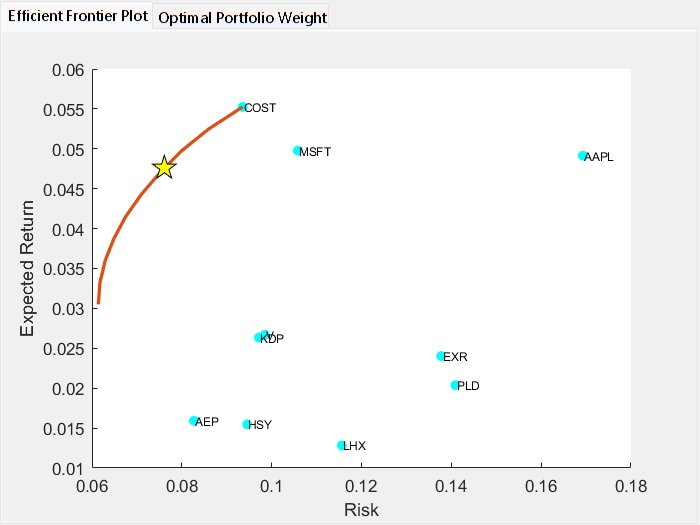

tab2 = uitab(tabgp,'Title','Optimal Portfolio Weight'); % Create tab

% Column names and column format
columnname = {'Ticker','Weight (%)'};
columnformat = {'char','numeric'};

% Define the data as a cell array
% Filter for assets with non-zero weights and ensure column vectors
nonZeroIdx = w1 > 0;
tickers = symbol(nonZeroIdx)';
weights = w1(nonZeroIdx) * 100;

% Force both to be column vectors
tickers = tickers(:);
weights = weights(:);

% Combine into table and convert to cell
data = table2cell(table(tickers, weights));

% Create the uitable
uit = uitable(tab2, 'Data', data,... 
            'ColumnName', columnname,...
            'ColumnFormat', columnformat,...
            'RowName',[]);

% Set width and height
uit.Position(3) = 450; % Widght
uit.Position(4) = 350; % Height